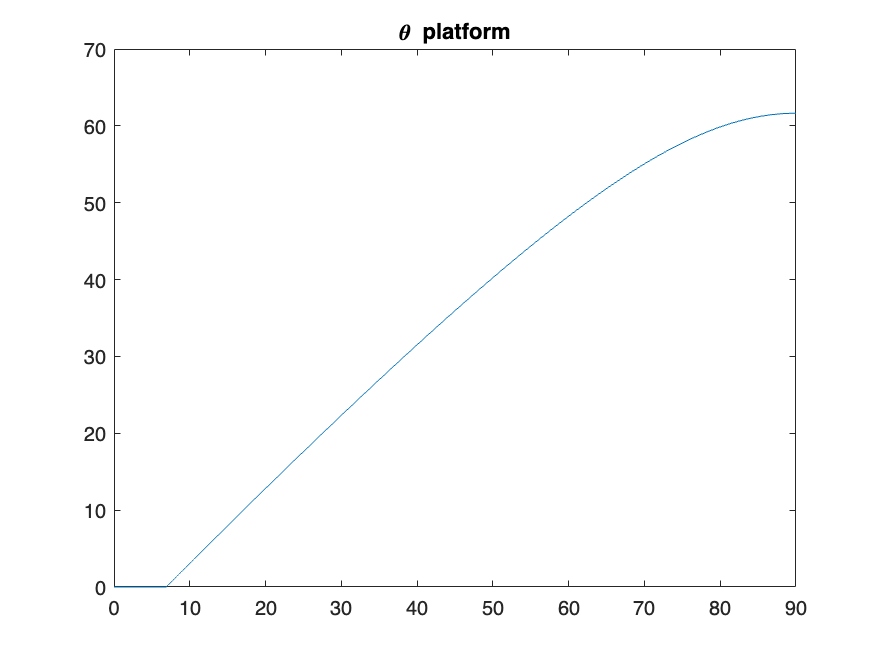

theta_max = [linspace(0,90,1000)]*pi/180;

cl = 2;
h_bak = 0.24;
theta_platform = asin((cl*sin(theta_max)-h_bak)/cl);
for i = 1:length(theta_platform)
    if theta_platform(i) < 0
        theta_platform(i) = 0;
    end
end
plot(theta_max*180/pi,theta_platform*180/pi)
title('\theta platform')

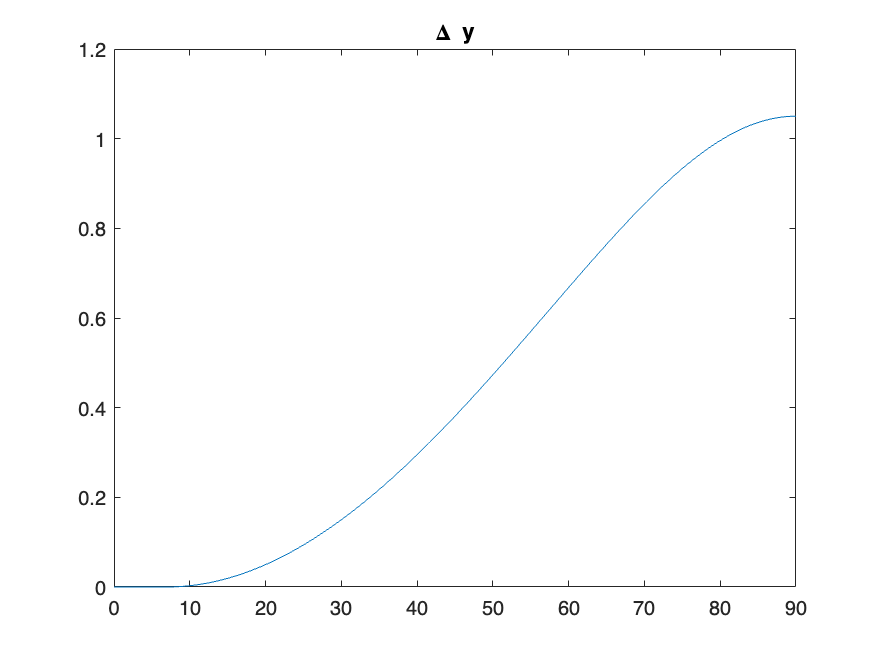

dy = cl -cl*cos(theta_platform);
plot(theta_max*180/pi,dy)
title('\Delta y')

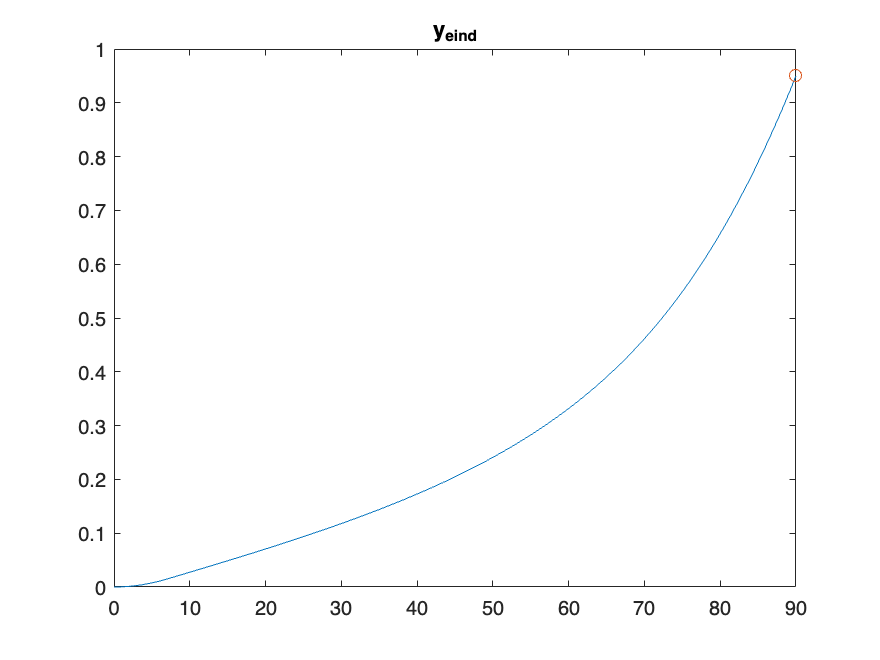

y_eind = cl - cl*cos(theta_max) -dy;
[M,I]= max(y_eind);
plot(theta_max*180/pi,y_eind)
hold on
scatter(theta_max(I)*180/pi , y_eind(I))
hold off
title('y_{eind}')

theta_max(I)*180/pi

ans = 90

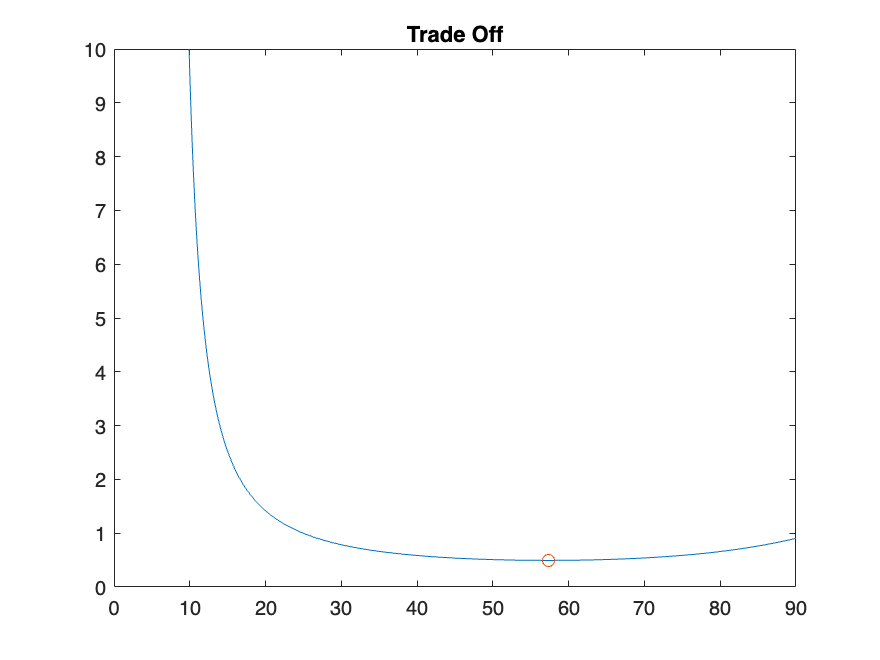


trade_off = y_eind./dy;
[M,I]= min(trade_off);
plot(theta_max*180/pi,trade_off)
hold on
scatter(theta_max(I)*180/pi , trade_off(I))
ylim([0,10])
title('Trade Off')

theta_max(I)*180/pi

ans = 57.2973